# OCI Correlation Bounds: Example 3.1

**Description**: Code to produce Example 3.1 of [1].

**Outputs**: none

**Assumptions and limitations**: none

**Other m-files required**: plotCov2.m, plotCov3.m

**MAT-files required**: none

**Toolboxes required**: none

**Authors**: Leonardo Pedroso, Pedro Batista, W.P.M.H. (Maurice) Heemels

**Revision history**:

- 20/01/2025 - First draft of full implementation (Leonardo Pedroso)

**References**:

[1] L. Pedroso, P. Batista, and W.P.M.H. Heemels, "Overlapping Covariance Intersection: Fusion with Partial Structural Knowledge of Correlation from Multiple Sources", 2025. (submitted)

## Initialization

clear;
epsl = 1e-5;
% Colorblind-safe color palette (Wong, B. Points of view: Color blindness.
% Nat Methods 8,441 (2011). https://doi.org/10.1038/nmeth.1618)
color.black = [0 0 0]/255;
color.orange = [230 159 0]/255;
color.cyan = [86 180 233]/255;
color.green = [0 158 115]/255;
color.yellow = [240 228 66]/255;
color.blue = [0 114 178]/255;
color.red = [213 94 0]/255;
color.pink = [204 121 167]/255;


## Example 1 (2D)

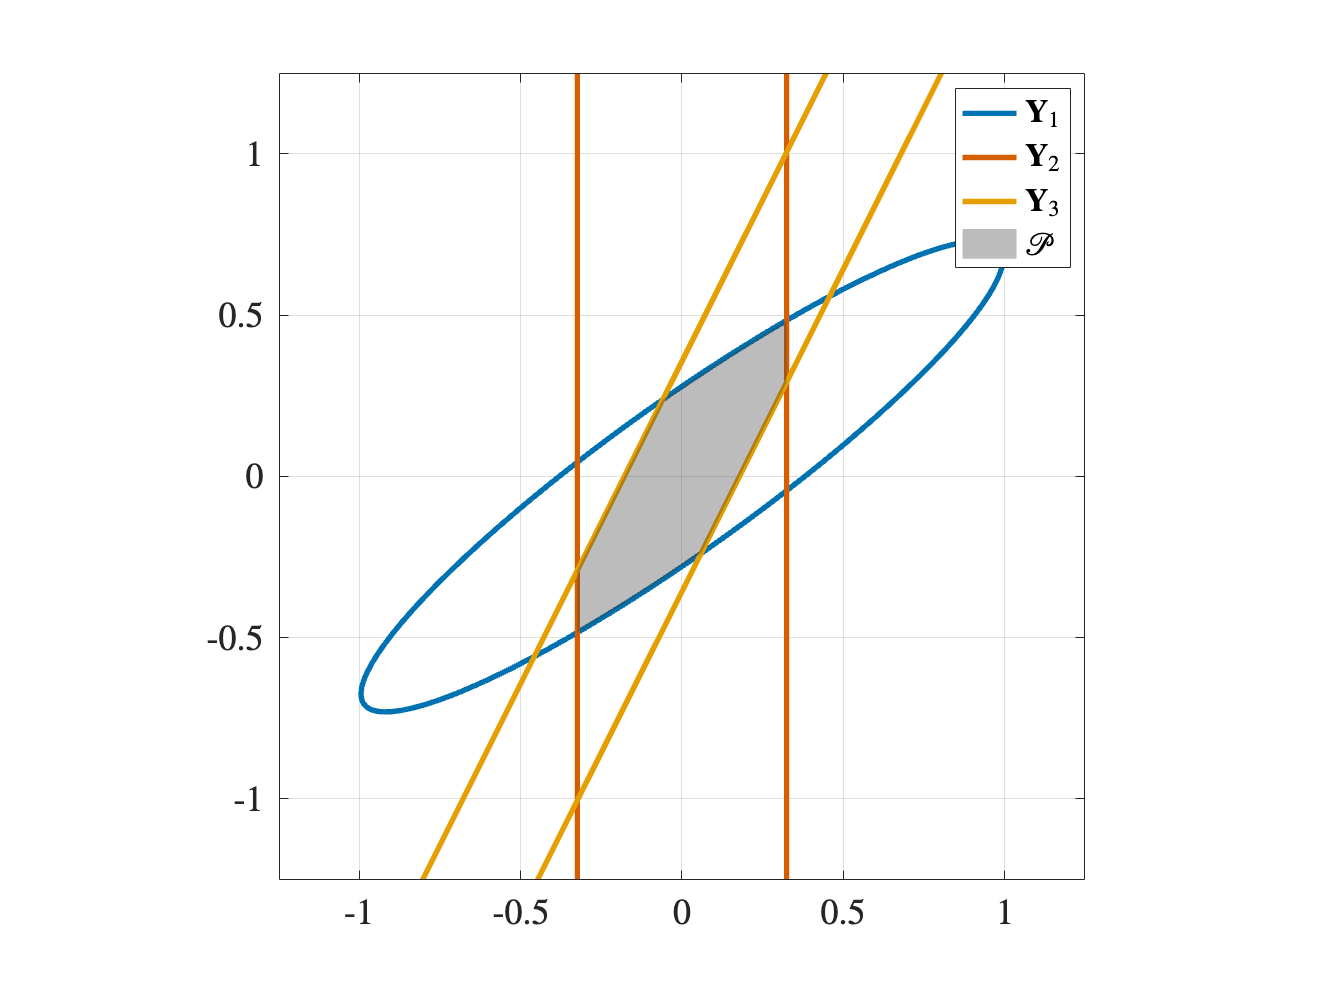

% Seed
seed = 62038;
rng(seed);

% Generate bounds
M = 3;
Xb = cell(M,1);
Wb = cell(M,1);
Yb = cell(M,1);

% 1. Normal bound (X<= Xb1)
Xb{1,1} = 2*(rand(2,2)-0.5);
Xb{1,1} = Xb{1,1}*Xb{1,1}';
% In this case it is the same as Y1 = inv(X1)
Wb{1,1} = eye(2);
Yb{1,1} = (Wb{1,1}'/Xb{1,1})*Wb{1,1};

% 2. Bound on an principal component (X_11 <= Xb2_11)
Wb{2,1} = [1 0];
Xb{2,1} = (rand(1,1)-0.5);
Xb{2,1} = Xb{2,1}*Xb{2,1}';
% Equivalent to
% X2 = [1 0;
%       0 +inf]
Yb{2,1} = (Wb{2,1}'/Xb{2,1})*Wb{2,1};

% 3. Bound on an nonprincipal component (X_11 <= Xb2_11)
Wb{3,1} = [2 -1];
Xb{3,1} = 6*(rand(1,1)-0.5);
Xb{3,1} = Xb{3,1}*Xb{3,1}';
Yb{3,1} = (Wb{3,1}'/Xb{3,1})*Wb{3,1};


% Plot elipsoids
elpsXb1 = plotCov2(Yb{1,1});
elpsXb2 = plotCov2(Yb{2,1}+epsl*eye(2));
elpsXb3 = plotCov2(Yb{3,1}+epsl*eye(2));
poly1 = polyshape(elpsXb1(1,1:end-1),elpsXb1(2,1:end-1));
poly2 = polyshape(elpsXb2(1,1:end-1),elpsXb2(2,1:end-1));
poly3 = polyshape(elpsXb3(1,1:end-1),elpsXb3(2,1:end-1));
intersect12 = intersect(poly1, poly2);
intersect123 = intersect(intersect12, poly3);
figure('Position',4*[0 0 192 144]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis
plot(elpsXb1(1,:),elpsXb1(2,:),'LineWidth',3,'Color',color.blue);
plot(elpsXb2(1,:),elpsXb2(2,:),'LineWidth',3,'Color',color.red);
plot(elpsXb3(1,:),elpsXb3(2,:),'LineWidth',3,'Color',color.orange);
plot(intersect123, 'FaceColor', 0.25*[1 1 1], 'EdgeColor', 'none');
legend({'$\mathbf{Y}_1$','$\mathbf{Y}_2$','$\mathbf{Y}_3$','$\mathcal{P}$'},'Interpreter','latex')
axis equal;
lim_axis = 0.25*max([max(elpsXb1(1,:)) max(elpsXb1(2,:))])+1;
xlim(lim_axis*[-1 1]);
ylim(lim_axis*[-1 1]);


% Save figure to .fig and .png formats
% savefig('./figures/eg1_2D.fig');
% set(gcf,'renderer','Painters');
% exportgraphics(gcf,'./figures/eg1_2D.pdf');

## Example 2 (3D)

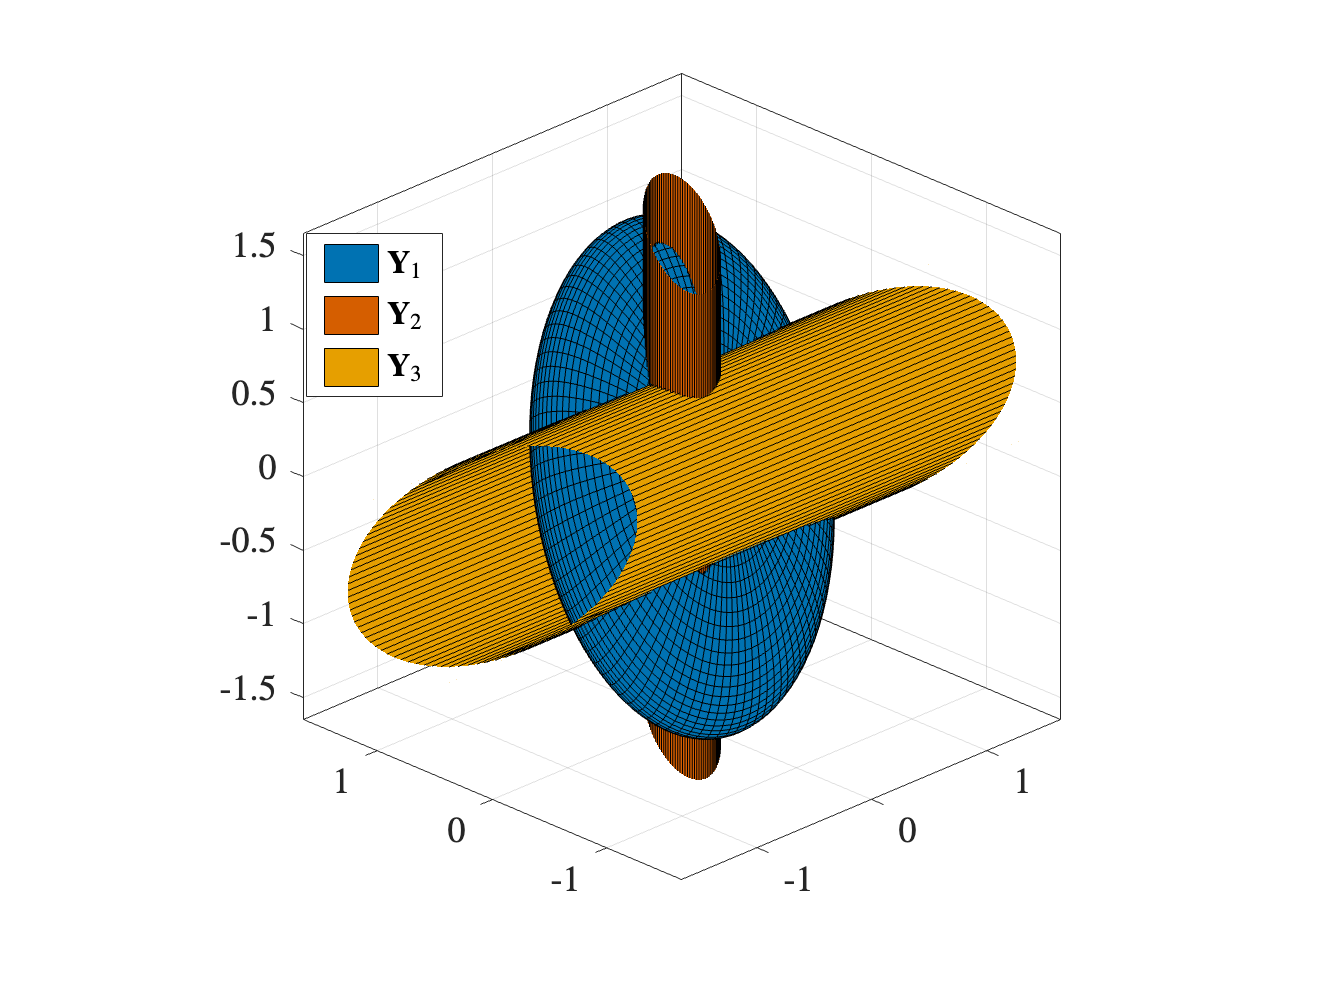

rng(98476);
M = 3;
Xb = cell(M,1);
Wb = cell(M,1);
Yb = cell(M,1);

% Running example
% 1. W1
Xb{1,1} = 2*(rand(3,3)-0.5);
Xb{1,1} = Xb{1,1}*Xb{1,1}';
% In this case it is the same as Y1 = inv(X1)
Wb{1,1} = eye(3);
Yb{1,1} = (Wb{1,1}'/Xb{1,1})*Wb{1,1};

% 2. W2
Wb{2,1} = [1 0 0; 0 1 0];
Xb{2,1} = 2*(rand(2,2)-0.5);
Xb{2,1} = Xb{2,1}*Xb{2,1}';
Yb{2,1} = (Wb{2,1}'/Xb{2,1})*Wb{2,1};

% 3. Bound on an nonprincipal component (X_11 <= Xb2_11)
Wb{3,1} = [0 1 0; 0 0 1];
Xb{3,1} = 2*(rand(2,2)-0.5);
Xb{3,1} = Xb{3,1}*Xb{3,1}';
Yb{3,1} = (Wb{3,1}'/Xb{3,1})*Wb{3,1};

% Plot elipsoids
[elpsXb1x,elpsXb1y,elpsXb1z] = plotCov3(Yb{1,1});
[elpsXb2x,elpsXb2y,elpsXb2z] = plotCov3(Yb{2,1}+epsl*eye(3));
[elpsXb3x,elpsXb3y,elpsXb3z] = plotCov3(Yb{3,1}+epsl*eye(3));
figure('Position',4*[0 0 192 144]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis
surf(elpsXb1x,elpsXb1y,elpsXb1z,'FaceAlpha', 1, 'EdgeColor', 'k', 'FaceColor', color.blue,'LineWidth',0.5);
surf(elpsXb2x,elpsXb2y,elpsXb2z,'FaceAlpha', 1, 'EdgeColor', 'k', 'FaceColor', color.red,'LineWidth',0.5);
surf(elpsXb3x,elpsXb3y,elpsXb3z,'FaceAlpha', 1, 'EdgeColor', 'k', 'FaceColor', color.orange,'LineWidth',0.5);
lighting gouraud; % Use Gouraud lighting for smooth shading
legend({'$\mathbf{Y}_1$','$\mathbf{Y}_2$','$\mathbf{Y}_3$'},'Interpreter','latex','Position',[0.2351,0.60253,0.097561,0.1565])
%camlight headlight; % Add a light for better visualization
%shading interp; 
axis equal;
lim_axis = 0.5*max([max(elpsXb1x) max(elpsXb1x)])+1;
xlim(lim_axis*[-1 1]);
ylim(lim_axis*[-1 1]);
zlim(lim_axis*[-1 1]);
view([-45 25]);


% Save figure to .fig and .png formats
% savefig('./figures/eg1_3D.fig');
% set(gcf,'renderer','opengl');
% exportgraphics(gcf,'./figures/eg1_3D.pdf','Resolution',600);